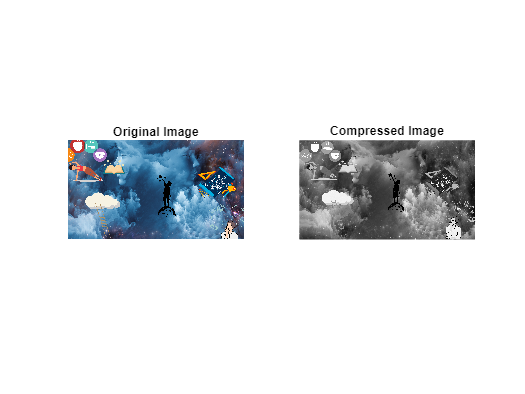



% Read the image
originalImage = imread('D:\projects\Black Yellow Aesthetic Samurai Desktop Wallpaper.png');

% Display the original image
figure;
subplot(1, 2, 1);
imshow(originalImage);
title('Original Image');

% Convert the image to grayscale if it's a color image
if size(originalImage, 3) == 3
    grayImage = rgb2gray(originalImage);
else
    grayImage = originalImage;
end

% Perform compression using Singular Value Decomposition (SVD)
[U, S, V] = svd(double(grayImage));

% Choose the number of singular values to keep (compression factor)
compressionFactor = 0.2; % Example: keeping only top 20% singular values

% Calculate the number of singular values to keep
numSingularValues = round(compressionFactor * min(size(S)));

% Truncate singular value matrices
U_compressed = U(:, 1:numSingularValues);
S_compressed = S(1:numSingularValues, 1:numSingularValues);
V_compressed = V(:, 1:numSingularValues);

% Reconstruct the compressed image
compressedImage = uint8(U_compressed * S_compressed * V_compressed');

% Display the compressed image
subplot(1, 2, 2);
imshow(compressedImage);
title('Compressed Image');


% Calculate compression ratio
originalSize = numel(grayImage);
compressedSize = numel(U_compressed) + numel(S_compressed) + numel(V_compressed);
compressionRatio = compressedSize / originalSize;
disp(['Compression Ratio: ' num2str(compressionRatio)]);

Compression Ratio: 0.335
